# **Project 2 - Monte Carlo Simulations**

**1. Generate a series **$(X_i, Y_i)$** for 𝑖 = 1, … , 𝑛 of Bivariate-Normally distributed random vectors, with the mean vector of (0,0) and the variance – covariance matrix of **$\left\lbrack \begin{array}{cc}
3 & a\\
a & 5
\end{array}\right\rbrack$**. Compute the following by simulation: **$\rho \left(a\right)=\frac{\frac{1}{n-1}\sum_{i=1}^n \left(X_i -\bar{X} \right)\left(Y_i -\bar{Y} \right)}{\sqrt{\frac{1}{n-1}\sum_{i=1}^n {\left(X_i -\bar{X} \right)}^2 }\sqrt{\frac{1}{n-1}\sum_{i=1}^n {\left(Y_i -\bar{Y} \right)}^2 }}$**  where **$\bar{X}$**=**$\sum_{i=1}^n X_i$**, **$\bar{Y}$**=**$\sum_{i=1}^n Y_i$**. Take n=1000 and a=-0.7**

a = -0.7;
n = 1000;
sigma1 = sqrt(3);
sigma2 = sqrt(5);
corr_rho = a/(sigma1*sigma2);
% generate normal distribution series
Z1 = generate_ND(n,1231);
Z2 = generate_ND(n,78);
% generate data with covariance
X = sigma1*Z1;
Y = sigma2*corr_rho*Z1 + sigma2*sqrt(1-corr_rho^2)*Z2;
% calculate rho
numerator = sum((X-mean(X)) .* (Y-mean(Y)))/(n-1);
denumerator = sqrt(sum(power(X-mean(X),2))/(n-1)) * sqrt(sum(power(Y-mean(Y),2))/(n-1));
final_rho = numerator/denumerator;
fprintf("final_rho: %.4f", final_rho)

final_rho: -0.2074

**2. Evaluate the following expected values by using Monte Carlo simulation: *****E=*****Ε [max(0, (**$X^3$**+**$\sin \left(Y\right)$**+**$X^2 Y$**)], where X and Y have N(0,1) distribution and a correlation of **$\rho$** = 0.6.  **

n=10000;
corr_rho = 0.6;
% generate normal distribution series
Z1_2 = generate_ND(n,11);
Z2_2 = generate_ND(n,78);
% generate data with covariance
X2 = 1*Z1_2;
Y2 = 1*corr_rho*Z1_2 + 1*sqrt(1-corr_rho^2)*Z2_2;
% compute E
sim_vector = max(0, power(X2, 3)+sin(Y2)+power(X2, 2).*Y2);
E = mean(sim_vector);
fprintf("expectation: %.4f", E)

expectation: 1.5398

**3. **

**(a) Estimate the following expected values by simulation:  **

**A(t) = E(**$W_t^2 +\sin \left(W_t \right)$**) and B(t) = E(**$e^{\frac{t}{2}}$**cos(**$W_t$**)) for 𝑡 = 1, 3, 5.**

**Here **$W_t$** is a Standard Wiener Process.  **

n=100000;
% generate normal distribution
W1 = generate_ND(n,11);
W3minus1 = generate_ND(n,7)*sqrt(3);
W5minus3 = generate_ND(n,13)*sqrt(2);

% W1, W3, W5
W3 = W1+W3minus1;
W5 = W3+W5minus3;

% A1, A3, A5
sim_A1 = power(W1,2)+sin(W1);
sim_A3 = power(W3,2)+sin(W3);
sim_A5 = power(W5,2)+sin(W5);
A1 = mean(sim_A1);
A3 = mean(sim_A3);
A5 = mean(sim_A5);
fprintf("A1: %.4f", A1)

A1: 1.0039

fprintf("A3: %.4f", A3)

A3: 4.0975

fprintf("A5: %.4f", A5)

A5: 6.2649

% B1, B3, B5
sim_B1 = exp(1/2)*cos(W1);
sim_B3 = exp(3/2)*cos(W3);
sim_B5 = exp(5/2)*cos(W5);
B1 = mean(sim_B1);
B3 = mean(sim_B3);
B5 = mean(sim_B5);
fprintf("B1: %.4f", B1)

B1: 1.0012

fprintf("B3: %.4f", B3)

B3: 0.6045

fprintf("B5: %.4f", B5)

B5: 0.6177

**(b) How are the values of B(t) (for the cases t = 1, 3, 5) related?  **

% correlation
% just the simulation
% covariance of B1, B3, B5
cov([reshape(sim_B1,[n,1]),reshape(sim_B3,[n,1]),reshape(sim_B5,[n,1])])

ans =     0.5432    0.3178   -0.2068
    0.3178    9.6615    9.5905
   -0.2068    9.5905   72.0553


% correlation of B1, B3, B5
corr([reshape(sim_B1,[n,1]),reshape(sim_B3,[n,1]),reshape(sim_B5,[n,1])])

ans =     1.0000    0.1387   -0.0331
    0.1387    1.0000    0.3635
   -0.0331    0.3635    1.0000


The correlation among B1, B3, and B5 are a little obvious. Especially, the correlation between B3 and B5 are pretty high (0.3635).

**(c).  Now use a variance reduction technique (whichever you want) to compute the expected value (t) for the case t = 5. Do you see any improvements? Comment on your findings.  **

% Antithetic Variates
sim_B5_pos = exp(5/2)*cos(W5);
sim_B5_neg = exp(5/2)*cos(-W5);
sim_B5_reduce = (sim_B5_pos+sim_B5_neg)/2;
B5_reduce_var = mean(sim_B5_reduce);
fprintf("B5: %.4f", B5_reduce_var)

B5: 0.6177

% variance
var(sim_B5_reduce)

ans = 72.0553

Since cos(-w) and cos(w) have the same value, antithetic variates method can only keep the variance no changes on this problem. So, there is no improvement.

**4. Let **$S_t$** be a Geometric Brownian Motion process: **$S_t$** = **$S_0$$e^{\left(\sigma W_t +\left(r-\frac{\sigma^2 }{2}\right)t\right)}$**, where r = 0.04, **$\sigma$**= 0.2, **$S_0$** = $88, **$W_t$** is a Standard Brownian Motion process (Standard Wiener process).**

**(a) Estimate the price c of a European Call option on the stock with T= 5, X = $100 *****by using Monte Carlo simulation.***  

r = 0.04;
sigma = 0.2;
S0 = 88;
T = 5;
X = 100;
% WT
WT = generate_ND(n,29)*sqrt(T);

% A1, A3, A5
sim_ST = S0*exp(sigma*WT + (r-power(sigma,2)/2)*T);
sim_c = exp(-r*T)*max(0,sim_ST-X);
call_option = mean(sim_c);
fprintf("estimated call option value: %.4f", call_option)

estimated call option value: 18.3618

% variance of the simulated call option values
var(sim_c)

ans = 1.0331e+03

**(b) Compute the exact value of the option c by the Black-Scholes formula.  **

d1 = (log(S0/X)+(r+power(sigma,2)/2)*T)/(sigma*sqrt(T));
d2 = d1 - sigma*sqrt(T);
BS_call_option = S0*normcdf(d1)-normcdf(d2)*X*exp(-r*T);
fprintf("Black-Scholes call option value: %.4f", BS_call_option)

Black-Scholes call option value: 18.2838

**(c) Now use variance reduction techniques (whichever you want) to estimate the price in part (a) again. Did the accuracy improve? Comment.  **

% Antithetic Variates
sim_ST_pos = S0*exp(sigma*WT + (r-power(sigma,2)/2)*T);
sim_ST_neg = S0*exp(sigma*(-WT) + (r-power(sigma,2)/2)*T);
sim_c_pos = exp(-r*T)*max(0,sim_ST_pos-X);
sim_c_neg = exp(-r*T)*max(0,sim_ST_neg-X);

sim_c_reduce = (sim_c_pos+sim_c_neg)/2;
call_option_reduce = mean(sim_c_reduce);
fprintf("call option price: %.4f", call_option_reduce)

call option price: 18.3026

% variance of the simulated call option values with Antithetic Variates
var(sim_c_reduce)

ans = 347.2792

I used Antithetic Variates. The variance of simulated series decreases from 1033.1 to 347.2792. So, the accuracy is improved. 

**5. (a) For each integer number n from 1 to 10, use 1000 simulations of **$S_n$** to estimate E(**$S_n$**), where **$S_t$** is a Geometric Brownian Motion process: **$S_t$** = **$S_0$$e^{\left(\sigma W_t +\left(r-\frac{\sigma^2 }{2}\right)t\right)}$**, where r = 0.04, **$\sigma$** = 0.18, **$S_0$** =$88. **

**Plot all of the above E(**$S_n$**), for n ranging from 1 to 10, in one graph.  **

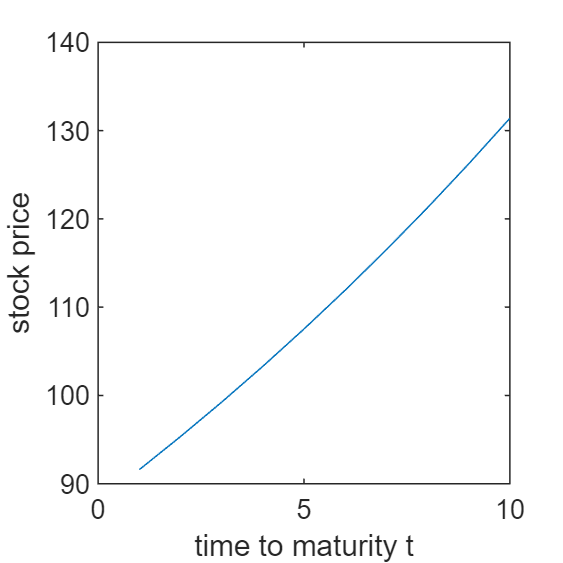

r = 0.04;
sigma = 0.18;
S0 = 88;
X = 100;
mean_S1 = 1:10;
for t = 1:10
    % WT
    Wt = generate_ND(1000,23);
    %St
    if t > 1
        S0 = mean_S1(t-1);
    end
    sim_St = S0*exp(sigma*Wt + (r-power(sigma,2)/2));
    mean_S1(t) = mean(sim_St);
end

% plot
plot(1:10, mean_S1)
set(gcf,'position',[100 100 250 250])
xlabel('time to maturity t') 
ylabel('stock price') 

**(b) Now simulate 6 paths of **$S_t$** for 0 ≤ t ≤ 10 (defined in part (a)) by dividing up the interval [0,10] into 1,000 equal parts.**

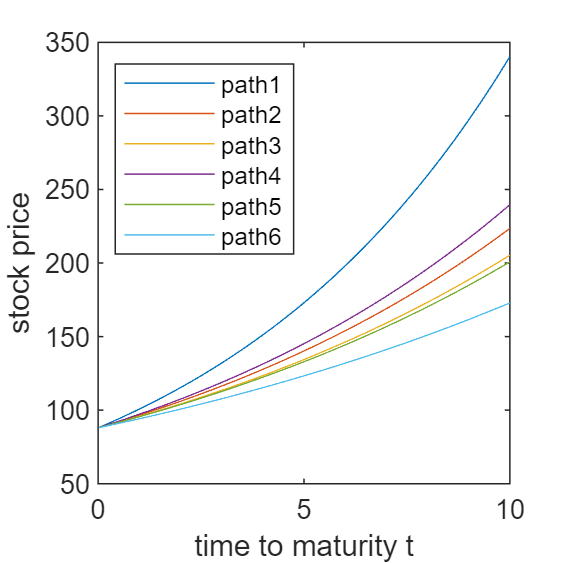

S_path = [];
for path = 1:6
    S0 = 88;
    mean_S = 1:1000;
    for i = 1:1000
        t = 10/1000;
        % WT
        Wt = generate_ND(1000,23*path+3)*sqrt(t);
        if i > 1
            S0 = mean_S(i-1);
        end
        % St
        sim_St = S0*exp(sigma*Wt + (r-power(sqrt(t),2)/2)*t);
        mean_S(i) = mean(sim_St);
    end
    S_path = [S_path; mean_S];
end

% transfrom data from matrix into dataset form
path_df = mat2dataset(S_path.');
path_df.Properties.VarNames = ["path1","path2","path3","path4","path5","path6"];

% plot
% build x axis
x_axis_vector = 1:1000;
x_axis_vector = x_axis_vector * 10/1000;

plot(x_axis_vector, path_df)
set(gcf,'Position',[100 100 250 250])
legend(path_df.Properties.VarNames,...
    'Location','northwest','NumColumns',1)
xlabel('time to maturity t') 
ylabel('stock price') 

(c) Plot your data from parts (a) and (b) in one graph.

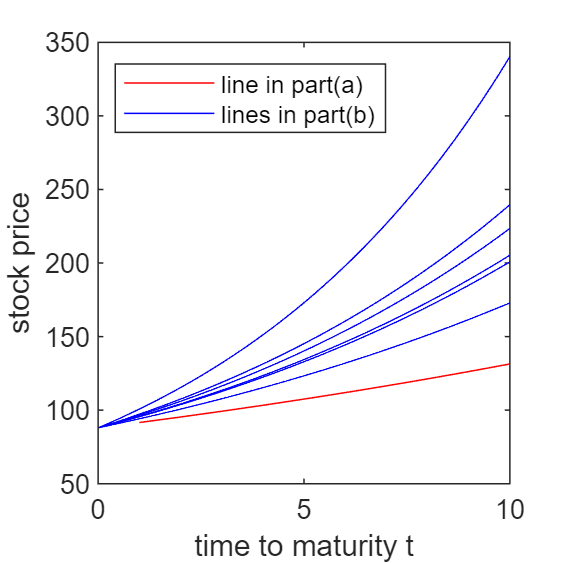

% plot the data in part(a)
h1 = plot(1:10, mean_S1,"r");
hold on
% plot the data in part(b)
h2 = plot(x_axis_vector, path_df,"b");
hold off
set(gcf,'Position',[100 100 250 250])
legend([h1(1),h2(1)],["line in part(a)","lines in part(b)"],...
    'Location','northwest','NumColumns',1)
xlabel('time to maturity t') 
ylabel('stock price') 

**(d) What would happen to the E(**$S_n$**) graph if you increased 𝜎 from 18% to 35%? What would happen to the 6 plots of **$S_t$** for 0 ≤ t ≤ 10, if you increased **$\sigma$** from 18% to 35%?  **

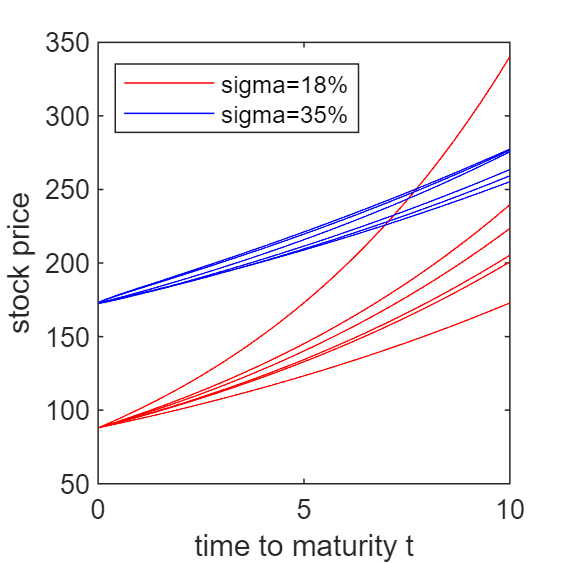

sigma_new = 0.35;
S_path2 = [];
for path = 1:6
    mean_S = 1:1000;
    for i = 1:1000
        t = 10/1000 * i;
        % WT
        Wt = generate_ND(1000,23*path)*sqrt(t);
        % WT
        sim_St = S0*exp(sigma_new*Wt + (r-power(sigma_new,2)/2)*t);
        mean_S(i) = mean(sim_St);
    end
    S_path2 = [S_path2; mean_S];
end

% transfrom data from matrix into dataset form
path_df2 = mat2dataset(S_path2.');
path_df2.Properties.VarNames = ["path1","path2","path3","path4","path5","path6"];

% plot
h1 = plot(x_axis_vector, path_df, "r");
hold on
h2 = plot(x_axis_vector, path_df2, "b");
hold off
set(gcf,'Position',[100 100 250 250])
legend([h1(1),h2(1)],["sigma=18%","sigma=35%"],...
    'Location','northwest','NumColumns',1)
xlabel('time to maturity t') 
ylabel('stock price') 

When the sigma increase from 18% to 35%, the variance of the 6 paths becomes larger (blue lines have larger disperation than red lines). And the stock price with higher sigma generally has larger average than that with lower sigma.

**6. Consider the following integral for computing the number **$\pi$**: 4**$\int_0^1 \sqrt{1-x^2 }\textrm{dx}=\pi$**.**

**(a) The integral above can be estimated by a simple numerical integration using, say Euler’s discretization (or any other discretization) scheme. Estimate the integral by using the Euler’s discretization scheme.**

I = 0;
for i = 1:500
    delta = 1/500;
    derivative_part = 4 * sqrt(1-(delta*(i-1))^2)*delta; 
    I = I + derivative_part;
end
fprintf('Estimated value of the integral by using the Euler’s discretization scheme: %.4f\n',I)

Estimated value of the integral by using the Euler’s discretization scheme: 3.1455


**(b) Estimate the integral by Monte Carlo simulation.**

nmax = 1000000;
x1 = generate_U(nmax,223);
series = 4*sqrt(1-power(x1,2)); 
thepi = mean(series);  
fprintf('Estimated value of the integral by Monte Carlo simulation: %.4f\n',thepi)

Estimated value of the integral by Monte Carlo simulation: 3.1407


**(c) Now try the Importance Sampling method to improve the estimate of **$\pi$** in part (b). Comment on errors and improvements.**

t_series = (1-0.74*power(x1,2))/(1-0.74/3);
% get pi value 
series_reduce = series./t_series ;  
thepi_reduce = mean(series_reduce);
fprintf('Estimated value of the integral by Monte Carlo simulation: %.4f\n',thepi_reduce)

Estimated value of the integral by Monte Carlo simulation: 3.1345


% error with Importance Sampling method
thepi_reduce-pi

ans = -0.0071

% variance with Importance Sampling method
var(series_reduce)

ans = 0.0990

% error without Importance Sampling method
thepi-pi

ans = -8.9380e-04


% variance without Importance Sampling method
var(series)

ans = 0.7994

  The variance with Importance Sampling method is 0.099 which is much lower than the variance without the methods (0.7994). So, Importance Sampling method decrease the variance a lot, although the mean value is no as close to $\pi$ as the one without Importance Sampling method. 

function ND_vector = generate_ND(num, seed)
% generate num normally distributed numbers ~ N(0,1)
    U1 = generate_U(num/2, seed);
    U2 = generate_U(num/2,seed*2+1);
    vector1 = sqrt(-2*log(U1)).*cos(2*pi*U2);
    vector2 = sqrt(-2*log(U1)).*sin(2*pi*U2);
    ND_vector = [vector1, vector2];
end
    
function U_vector = generate_U(num, seed) 
% generate num uniformly distributed numbers in [0,1] 
    m = pow2(31)-1;
    a = power(7,5)+3;
    X_vector = 1:num;
    for i = 1:num
        if i == 1
            % use 1 as X_0
            X_vector(i) = mod(a*seed,m);
        else
            % generate next X based on current X
            X_vector(i) = mod(a*X_vector(i-1),m);
        end
    end
    % divide X by m
    U_vector = X_vector/m;
end